# Simple vector interpolation

clear ; close ; path=pwd();
[s,e]=regexp(path,'.+(?=[\\/]{1,2}examples)');
path=path(s:e); addpath(genpath(path)); clear s e path

## 1) Definition of the domain

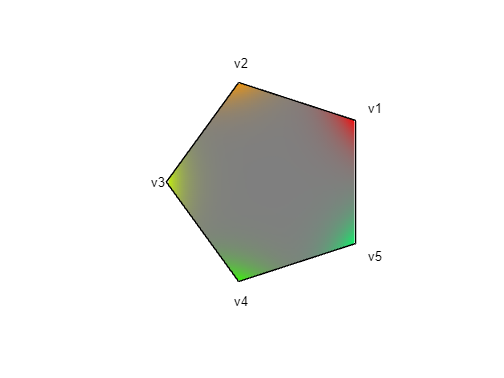

domain2D = Domain(5); % regular pentagon
figure()
domain2D.plot();

## 2) Definition of the vector properties at each vertex

dimInput = 2; dimOutput = 2;
f1v = VertexFunction(@(b) b.^2, @(b) [2*b(1,1,:),zeros(1,1,size(b,3));zeros(1,1,size(b,3)),2*b(2,1,:)], "b.^2", dimInput, dimOutput);
f2v = VertexFunction(@(b) b.^3, @(b)  [3*b(1,1,:).^2,zeros(1,1,size(b,3));zeros(1,1,size(b,3)),3*b(2,1,:).^2], "b.^3", dimInput, dimOutput);
f3v = VertexFunction(@(b) 0.1*b, @(b) ones(size(b)).*eye(2)*0.1, "0.1*a", dimInput, dimOutput); % linear
f4v = VertexFunction(@(b) ones(size(b)), @(b) zeros(2,2,size(b,3)), "[1;1]", dimInput, dimOutput); % constant
f5v = VertexFunction(@(b) mult([1,2;3,4],b), @(b) [1,2;3,4].*ones(1,1,size(b,3)), "K*b", dimInput, dimOutput);

## 3) Definition of the interpolation

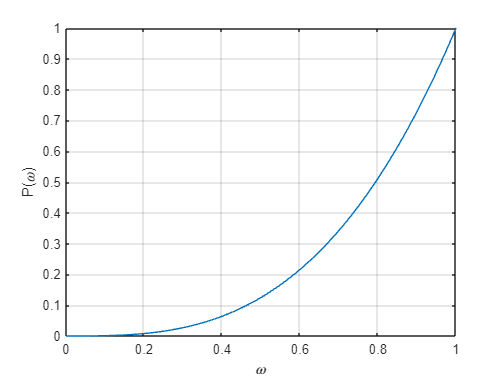

defInterpVector.Domain = domain2D;
defInterpVector.Children = [f1v,f2v,f3v,f4v,f5v];
defInterpVector.Label = "interpVector";

P = Penalization("simp",3);
defInterpVector.Penalization = P;
P.plot();


interpVector=Interpolation(defInterpVector);

## 4) Definition of the variables

### a) Coordinates in the polygon

n = 1e4; % number of evaluation points
x = interpVector.initializeVariable(n,"rand",0.4)

x = struct with fields:
    interpVector: [10000×2 double]


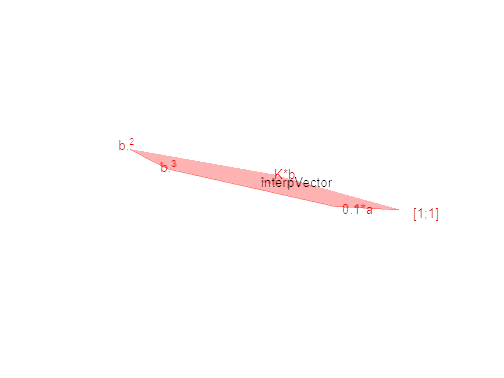

x = interpVector.projection(x);
figure()
interpVector.plot(x);

### b) Vector field

Each point $x$ is associated to a vector field value $b$.

b = rand(2,1,n);

## 5) Evaluation of the interpolation

### a) Interpolated value

tic
val = interpVector.eval(x,b); % value
tv1 = toc;
disp(strcat("Compute interpolated values in ",num2str(tv1*1000)," ms"))

Compute interpolated values in 10.421 ms


### b) Derivative w. r. t. the scalar field

tic
dvaldb =  interpVector.evalda(x,b); % derivative w.r.t b
tdb1 = toc;
disp(strcat("Compute interpolated b-derivative in ",num2str(tdb1*1000)," ms"))

Compute interpolated b-derivative in 11.3656 ms


#### Check the Taylor expansion

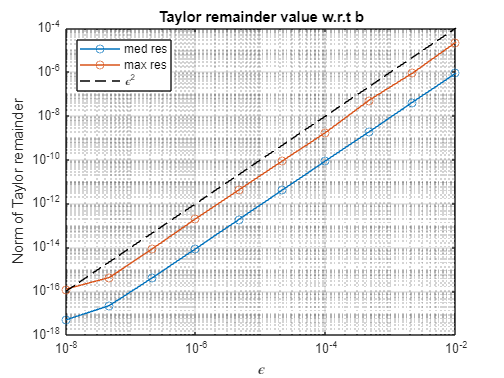

epsilon = logspace(-8,-2,10); % test for different epsilon
res = zeros(10,1,n);
for i=1:10
    bpert = epsilon(i)*rand(size(b));
    valPerturbedb = interpVector.eval(x,b+bpert);
    res(i,1,:) = vecnorm(valPerturbedb - (val + mult(dvaldb,bpert)),2,1);
end
MaxRes = max(res,[],3); medRes = median(res,3);
loglog(epsilon,medRes,'-o',epsilon,MaxRes,'-o',epsilon,epsilon.^2,'k--');
legend("med res","max res","\epsilon^2","Location","northwest")
xlabel("\epsilon")
ylabel("Norm of Taylor remainder")
title("Taylor remainder value w.r.t b")
grid on

### c) Derivative w. r. t. the position in the interpolation domain

tic
dvaldx =  interpVector.evaldx(x,b); % derivative w.r.t x
tdx1 = toc;
disp(strcat("Compute interpolated x-derivative in ",num2str(tdx1*1000)," ms"))

Compute interpolated x-derivative in 7.4304 ms


#### Check the Taylor expansion

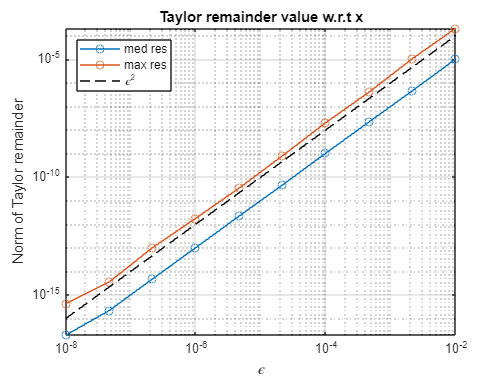

epsilon = logspace(-8,-2,10); % test for different epsilon
res = zeros(10,1,n);
l = defInterpVector.Label;

for i=1:10
    pert = epsilon(i)*rand(size(x.(l)));
    xPert.(l) = x.(l) + pert;
    valPerturbedx = interpVector.eval(xPert,b);
    pert = reshape(pert.',2,1,[]);
    res(i,1,:) = vecnorm(valPerturbedx - (val + mult(dvaldx.(l),pert)),2,1);
end
MaxRes = max(res,[],3); medRes = median(res,3);
loglog(epsilon,medRes,'-o',epsilon,MaxRes,'-o',epsilon,epsilon.^2,'k--');
legend("med res","max res","\epsilon^2","Location","northwest")
xlabel("\epsilon")
ylabel("Norm of Taylor remainder")
title("Taylor remainder value w.r.t x")
grid on

### d) Speed tip

To compute several times the interpolation for different $a$ without changing the position $x$ in the domain, one should first compute the shape functions once for all.

b2 = rand(2,100,n);
% slow
tic
for i=1:100
    interpVector.eval(x,b2(:,i,:)); % value
    interpVector.evalda(x,b2(:,i,:)); % derivative w.r.t a
    interpVector.evaldx(x,b2(:,i,:)); % derivative w.r.t x
end
tslow = toc;
disp(strcat("Computation time : ",num2str(tslow)," s"))

Computation time : 2.0458 s



% fast
tic
 % pre-computation of the shape functions
[w,dwdx] = interpVector.evalBasisFunction(x);
for i=1:100
    interpVector.eval(x,b2(:,i,:),w); % value
    interpVector.evalda(x,b2(:,i,:),w); % derivative w.r.t a
    interpVector.evaldx(x,b2(:,i,:),w,dwdx); % derivative w.r.t x
end
tfast = toc;
disp(strcat("Computation time : ",num2str(tfast)," s"))

Computation time : 1.3209 s
